Load data

clear
load mnist.mat

PCA

m = linspace(0,0,784)'; %mean
eigen = []; %eigen vectors
lambda = []; %eigen values
for c = 0:9
    digits = digits_train(:,:,labels_train == c); %all the images of a particular digit
    train = reshape(im2double(digits),[784 size(digits,3)]); %reshaping the images
    me = (sum(train,2)/size(train,2));
    m(:,c+1) = me;
    train = train - me;
    co = train*train' / size(train,2); %covariance matrix
    [u, s, v] = svd(co);
    eigen(:,c+1) = u(:,1);
    lambda(:,c+1) = diag(s);
end

Graph of the eigen-vectors

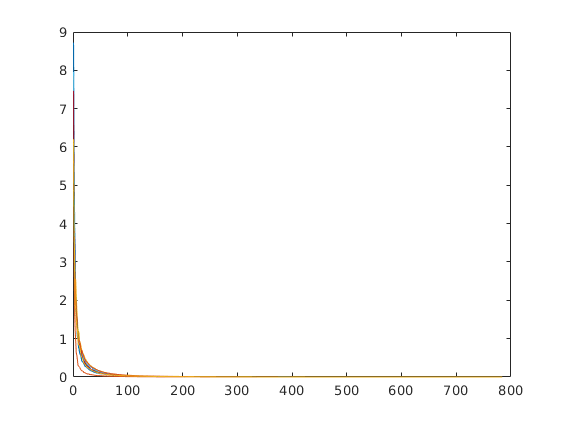

figure, plot(lambda)

Visualising the various photos

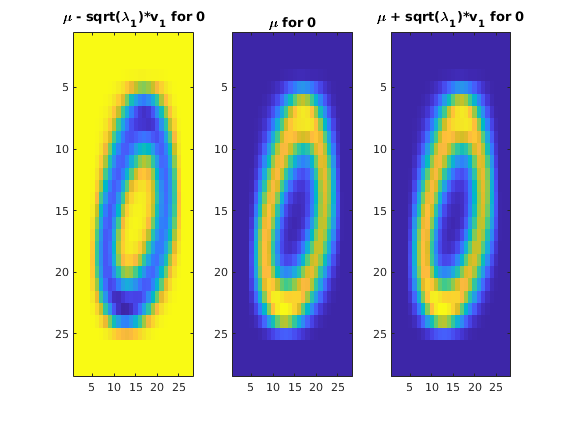

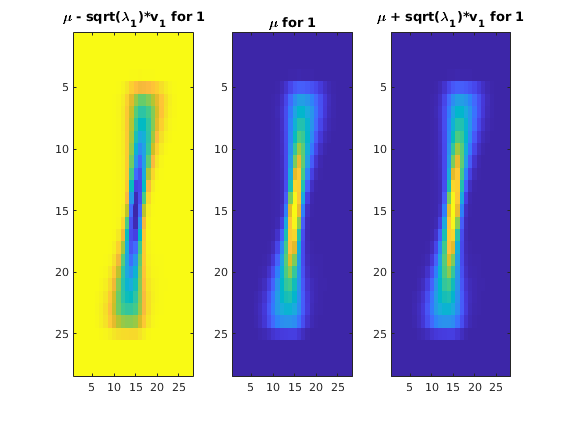

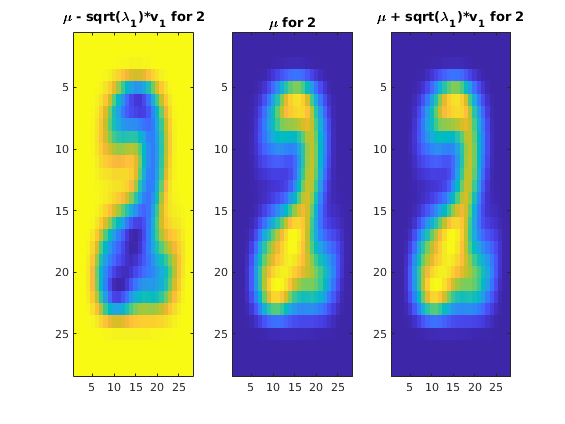

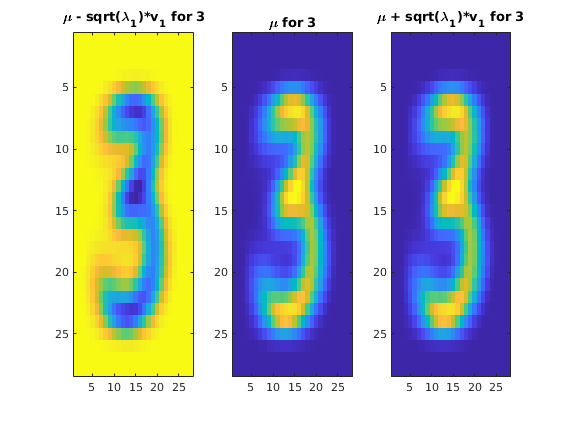

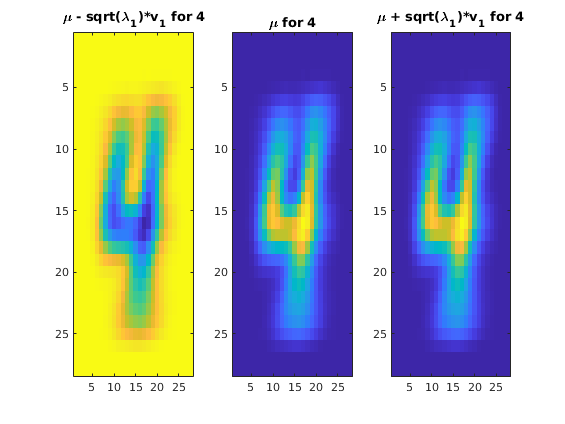

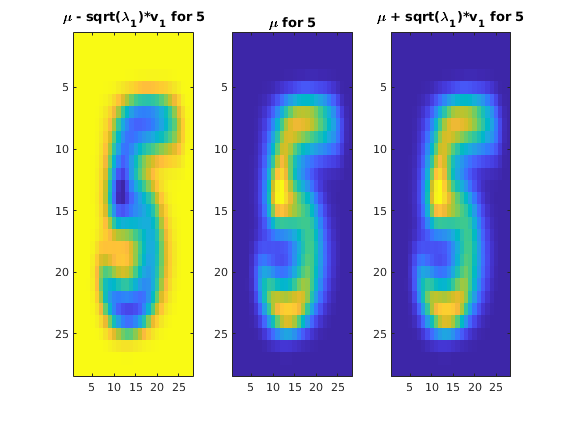

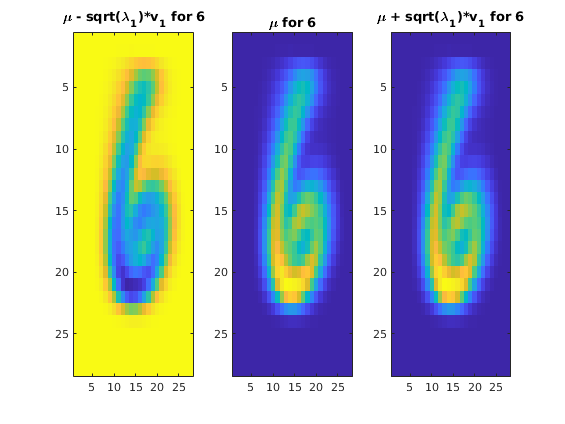

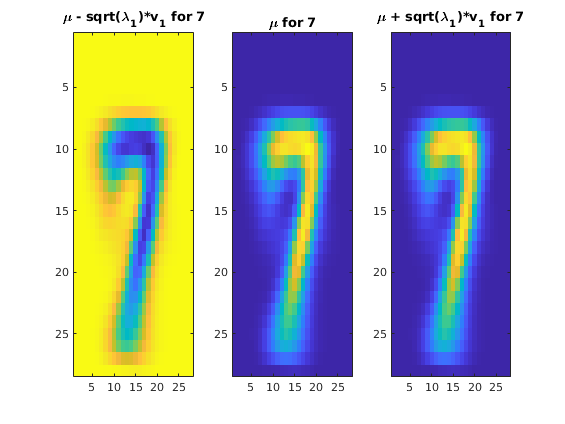

for i = 1:10
    figure, subplot(1,3,1);
    imagesc(reshape(m(:,i) - sqrt(lambda(i,1))*m(:,i),[28 28]));
    title("\mu - sqrt(\lambda_1)*v_1 for " + string(i-1))
    subplot(1,3,2); imagesc(reshape(m(:,i),[28 28]));
    title("\mu for " + string(i-1))
    subplot(1,3,3); imagesc(reshape(m(:,i) + sqrt(lambda(i,1))*m(:,i),[28 28]));
    title("\mu + sqrt(\lambda_1)*v_1 for "  + string(i-1))
end